load("experiment.txt")
time=experiment(:,1);
input=experiment(:,2);
output=experiment(:,3);
offset_t=time(1);
offset_i=input(1);
offset_o=output(1);

input=input-offset_i;
output=output-offset_o;
z=tf([1 0],1,0.01);
N=5;
H_5=1/((N)*z^(N-1));
for i=1:N-1
    H_5=H_5+(z^i/((N)*z^(N-1)));
end
N=20;
H_20=1/((N)*z^(N-1));
for i=1:N-1
    H_20=H_20+(z^i/((N)*z^(N-1)));
end

output_H_5=lsim(H_5,output,time);

output_H_20=lsim(H_20,output,time);


ss=output_H_20(length(output_H_20));
Mp=(max(output_H_20)-ss)/ss;
zeta=abs(log(Mp))/sqrt(pi^2+(2*(abs(log(Mp)))));
Kdc=ss/input(length(input));

tp=time(find(output_H_20==(max(output_H_20))))-40;

S=stepinfo(output_H_20,time-40,"SettlingTimeThreshold",0.01)

S = struct with fields:
        RiseTime: 0.6515
    SettlingTime: 14.9651
     SettlingMin: 34.9233
     SettlingMax: 94.4962
       Overshoot: 58.5421
      Undershoot: 5.1107
            Peak: 94.4962
        PeakTime: 2.0500


tp=S.PeakTime;
ts_5=S.SettlingTime;
tr=S.RiseTime*2;

x=1;
rta=100;
while true
    if output_H_20(x)<ss
        rta=output_H_20(x);
    else
        break        
    end
x=x+1;    
end

trx=time(x)-40;

omega_tp=pi/(tp*sqrt(1-zeta^2));
omega_tr=1.8/tr;
omega_ts=3/(zeta*ts_5);

s=tf([1 0],1);

G_tp=Kdc*(omega_tp^2)/(s^2+2*zeta*omega_tp*s+omega_tp^2);
G_ts=Kdc*(omega_ts^2)/(s^2+2*zeta*omega_ts*s+omega_ts^2);
G_tr=Kdc*(omega_tr^2)/(s^2+2*zeta*omega_tr*s+omega_tr^2);

y_tp=lsim(G_tp,input,time);

y_ts=lsim(G_ts,input,time);

y_tr=lsim(G_tr,input,time);

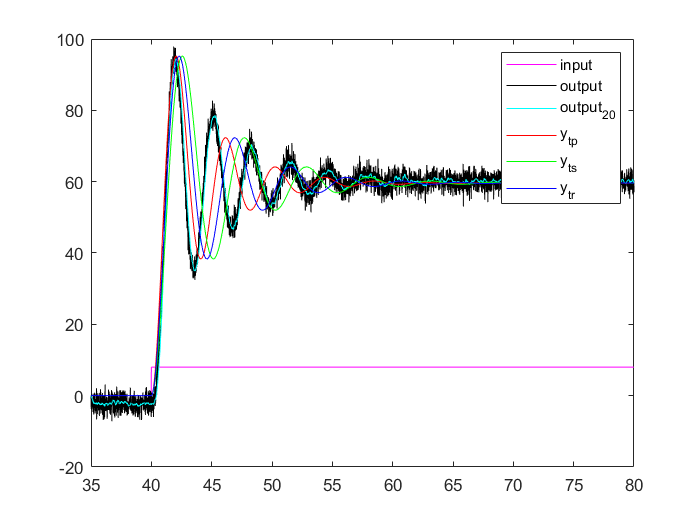

figure 
plot(time,input,'m')
hold on
plot(time,output,'k')
hold on 
plot(time,output_H_20,'c')
hold on
plot(time,y_tp,'r')
hold on
plot(time,y_ts,'g')
hold on 
plot(time,y_tr,'b')
legend('input','output','output_{20}','y_{tp}','y_{ts}','y_{tr}')

e_tp=output_H_20-y_tp;
e_ts=output_H_20-y_ts;
e_tr=output_H_20-y_tr;
dt=abs(time(2)-time(1));

IAE_tp=dt*sum(abs(e_tp));
IAE_ts=dt*sum(abs(e_ts));
IAE_tr=dt*sum(abs(e_tr));

ITAE_tp=dt*sum((time-40).*abs(e_tp));
ITAE_ts=dt*sum((time-40).*abs(e_ts));
ITAE_tr=dt*sum((time-40).*abs(e_tr));
